# Orientation Kinematics

clear; clc; close all;

In this document, we will think about kinematics of orientations in 3D space. Additionally, we will adopt reference frame conventions similar to those used in Pinocchio, for smoother transitions to implementing on hardware. The reference frames considered will be:

- O: World Frame

- B: Local Frame (Body Frame)

- A: World Aligned Local Frame

The code below considers a rigid body, located at position (1,1,1), with roll and pitch angles of 45deg. The given frames are visualized:

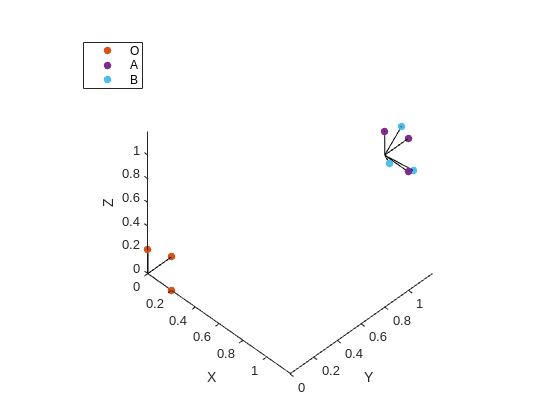

p = [1 1 1]';
roll_deg = 45;
pitch_deg = 45;

fh1 = figure();
plot_frame(fh1, [0,0,0]', eye(3), 'rot', 'O')
plot_frame(fh1, p, eye(3), 'rot', 'A')
plot_frame(fh1, p, eul2rotm(deg2rad([roll_deg, pitch_deg, 0]), 'XYZ'), 'rot', 'B')

## Representing Orientation and Pose

There are several ways of representing orientations and poses of rigid bodies in 3D space. The translational component is straightforward to represent, composed of a vector $p \in \mathbb{R}^3$. The rotational component is accompanied by a choice; several representations (such as euler angles, or any 3-number parameterization) have singularities, while others (requiring 4 or more numbers) are singularity free. Singular representations work if orientations do not deviate far from an operating point, but singularity free represenations are much cleaner. Therefore, we will primarily consider singularity free representations, namely the rotation matrix, $R \in SO(3)$, and the quaterion $q \in S^3$. 

### Rotation Matrices

A rotation matrix encodes the orientation of a rigid body by locating the axes of the body frame ($B$) in the world frame ($O$). In general, take the matrix $R_{ab} \in SO(3)$ to be a rotation matrix expressing the orientation of frame $B$ in reference to the frame $A$.  

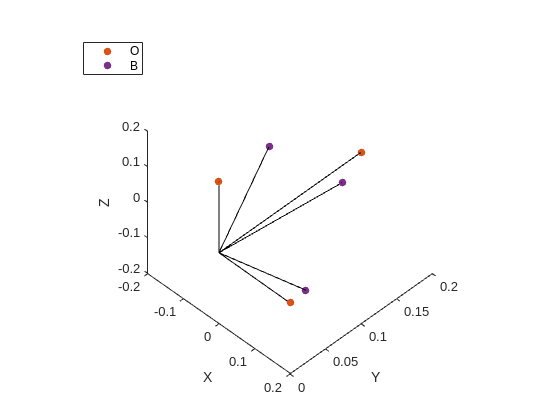

x = [1 1 1]'; x = x / norm(x);
y = [0.5 0.5 -1]'; y = y / norm(y);
z = cross(x, y);

R_ob = [x y z];
fh2 = figure();
plot_frame(fh2, [0,0,0]', eye(3), 'rot', 'O')
plot_frame(fh2, [0,0,0]', R_ob, 'rot', 'B')

### Quaternions

Quaterions represent the orientation of a rigid body by a 4-tuple of numbers, which have unit magnitude.  The set of quaternions double-cover the space of rotations, as a quaternion and its negative represent the same orientation.

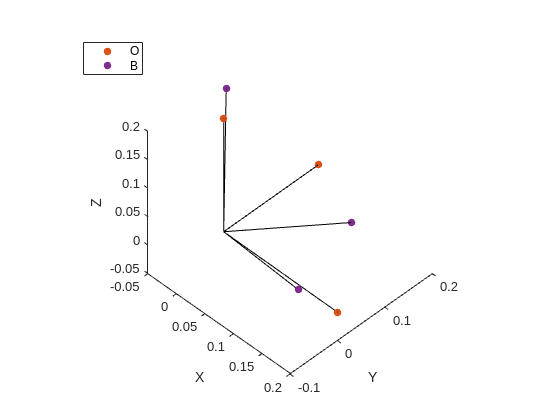

q = rand(1, 4); q = q / norm(q);
fh3 = figure();
plot_frame(fh3, [0,0,0]', eye(3), 'rot', 'O')
plot_frame(fh3, [0,0,0]', q, 'quat', 'B')

## Coordinate Transformations

Consider a vector $v \in \mathbb{R}^3$ and a point $p \in \mathbb{R}^3$. These quantities can be expressed with respect to any coordinate frame. 

### Rotation Matrices

If a vector is expressed in a coordinate frame $B$, then the same vector can be expressed in coordinate frame $A$ by using the rotation matrix as a transformation:


$$v_a = R_{ab} v_b$$


Intitution for this can be gathered by considering unit vectors in the $B$ frame, and how these corrospond to columns of the rotation matrix. Multiple coordinate transforms can be chained together by continuing left multiplication:


$$v_a = R_{ab} R_{bc} v_c$$


### Exponential Coordinates

A rotation can also by expressed as rotation about an axis $\omega$ (unit vector) by an angle $\theta$ (according to the right hand rule). This can be encoded by


$$R(\omega, \theta) = e^{\hat{\omega} \theta}$$


Where $e^{(\cdot)}$ is the matrix exponential and $\hat{\omega} = \left[\matrix{0 & -\omega_3 & \omega_2 \cr \omega_3 & 0 & -\omega_1 \cr -\omega_2 & \omega_1 & 0} \right]$, such that $\hat{\omega} v = \omega \times v$. The result is precisely the rotation matrix corrosponding to the angle-axis rotation.

### Quaternions

Quaternions have a product operation; unit quaternions form a group under the multiplication operations. Additionally, they are represented easily as axis-angle: $q = (q_0, \vec{q})$ (in w,x,y,z format) corrosponds to $(\omega, \theta)$ angle axis representation by $q_0 = \cos(\theta / 2)$, $\vec{q} = \omega \sin(\theta / 2)$. 

% function [omega, theta] = quat2aa(q)
% theta = 2 * acos(q(1));
% if theta == 0
%     omega = zeros(3, 1);
% else
%     omega = q(2:4)' / sin(theta / 2);
% end
% end
% 
% function q = aa2quat(omega, theta)
% omega = omega / norm(omega);
% q = [cos(theta / 2) omega' * sin(theta / 2)];
% end
% 
% function R = aa2rot(omega, theta)
% o = omega / norm(omega);
% R = expm([0 -o(3) o(2); o(3) 0 -o(1); -o(2) o(1) 0] * theta);
% end
% 
% function [omega, theta] = rot2aa(R)
% theta = acos((trace(R) - 1) / 2);
% if theta == 0
%     omega = zeros(3, 1);
% else
%     omega = [R(3, 2) - R(2, 3), R(1,3) - R(3,1), R(2,1) - R(1,2)]' / (2 * sin(theta));
% end
% end

Now, check to make sure each of these transformations works

% Random angle-axis
aa.theta = rand() * 2 * pi - pi;
aa.omega = rand(3, 1) - 0.5; aa.omega = aa.omega / norm(aa.omega);

aaq = quat2aa(aa2quat(aa));
assert(norm(aa.theta - aaq.theta) + norm(aa.omega - aaq.omega) < 1e-3 | ...
    norm(aa.theta + aaq.theta) + norm(aa.omega + aaq.omega) < 1e-3)

R = aa2rot(aa);
aaR = rot2aa(R);
assert(norm(aa.theta - aaR.theta) + norm(aa.omega - aaR.omega) < 1e-3 | ...
    norm(aa.theta + aaR.theta) + norm(aa.omega + aaR.omega) < 1e-3)

[w, x, y, z] = parts(randrot()); q = [w, x, y, z];
qaa = aa2quat(quat2aa(q));
assert(norm(q - qaa) < 1e-4)

R = quat2rotm(randrot());
Raa = aa2rot(rot2aa(R));
assert(norm(R - Raa) < 1e-4);

disp("Asserts passed")

Asserts passed


### Chaining Coordinate Transforms

Consider a set of three coordinate frames, $O, A, B$. Assume that $R_{oa}, R_{ab}$ are known, i.e. frame $A$ is defined relative to $O$, and frame $B$ is defined relative to $A$. Then frame $B$ expressed in frame $O$ is defined: $R_{ob} = R_{oa} R_{ab}$. 

A similar result holds for quaterions; given $q_{oa}, q_{ab}$ we have $q_{ob} = q_{oa} \cdot q_{ab}$, with $(\cdot)$ being quaternion multiplication. Check this result:

[w, x, y, z] = parts(randrot()); q_oa = [w, x, y, z];
[w, x, y, z] = parts(randrot()); q_ab = [w, x, y, z];

R_oa = aa2rot(quat2aa(q_oa));
R_ab = aa2rot(quat2aa(q_ab));

q_ob = quat_mult(q_oa, q_ab);
R_ob = R_oa * R_ab;

R_ob_q = aa2rot(quat2aa(q_ob));
assert(norm(R_ob - R_ob_q) < 1e-4)
disp("Asserts passed")

Asserts passed
